# LMSフィルタ比較

## ステップサイズによる比較

fleng     = 20;     %タップ数

fsize     = 5000;    %フレームサイズ


ssize = 0.1;   %ステップサイズ
lmsfilt1 = dsp.LMSFilter('Length',fleng,'Method','LMS', 'StepSize',ssize);

ssize = 0.05;
lmsfilt2 = dsp.LMSFilter('Length',fleng,'Method','LMS', 'StepSize',ssize);

ssize = 0.001;
lmsfilt3 = dsp.LMSFilter('Length',fleng,'Method','LMS', 'StepSize',ssize);

ssize = 0.0005;
lmsfilt4 = dsp.LMSFilter('Length',fleng,'Method','LMS', 'StepSize',ssize);

## ノイズ

Hp = dsp.ColoredNoise('Color','pink','SamplesPerFrame',fsize);
dp = Hp();

Hw = dsp.ColoredNoise('Color','white','SamplesPerFrame',fsize);
dw = Hw();

firfilt = dsp.FIRFilter('Numerator', fir1(10,[.5, .75]));

xp = firfilt(dp);
xw = firfilt(dw);

TS1 = dsp.TimeScope('TimeSpan',1.1*fsize*NI,'TimeUnits','Seconds',...
    'YLimits',[-3 3],'BufferLength',4*fsize*NI, ...
    'ShowLegend',true,'ChannelNames', ...
    {'Noisy signal', 'err'},'Title','0.1');
TS2 = dsp.TimeScope('TimeSpan',1.1*fsize*NI,'TimeUnits','Seconds',...
    'YLimits',[-3 3],'BufferLength',4*fsize*NI, ...
    'ShowLegend',true,'ChannelNames', ...
    {'Noisy signal', 'err'},'Title','0.05');
TS3 = dsp.TimeScope('TimeSpan',1.1*fsize*NI,'TimeUnits','Seconds',...
    'YLimits',[-3 3],'BufferLength',4*fsize*NI, ...
    'ShowLegend',true,'ChannelNames', ...
    {'Noisy signal', 'err'},'Title','0.001');
TS4 = dsp.TimeScope('TimeSpan',1.1*fsize*NI,'TimeUnits','Seconds',...
    'YLimits',[-3 3],'BufferLength',4*fsize*NI, ...
    'ShowLegend',true,'ChannelNames', ...
    {'Noisy signal', 'err'},'Title','0.0005');
TSe = dsp.TimeScope('TimeSpan',1.1*fsize*NI,'TimeUnits','Seconds',...
    'YLimits',[-3 3],'BufferLength',4*fsize*NI, ...
    'ShowLegend',true,'ChannelNames', ...
    {'LMS', 'NLMS', 'AP', 'RLS'},'Title','Err');

## ホワイトノイズ

% [~,e] = lmsfilt1(dw,xw);
% TS1([xw,e]);
% [~,e] = lmsfilt2(dw,xw);
% TS2([xw,e]);
% [~,e] = lmsfilt3(dw,xw);
% TS3([xw,e]);
% [~,e] = lmsfilt4(dw,xw);
% TS4([xw,e]);

## ピンクノイズ

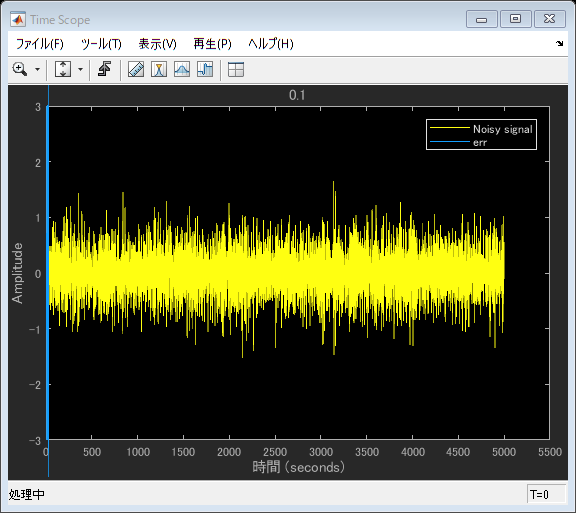

[~,e] = lmsfilt1(dp,xp);
TS1([xp,e]);

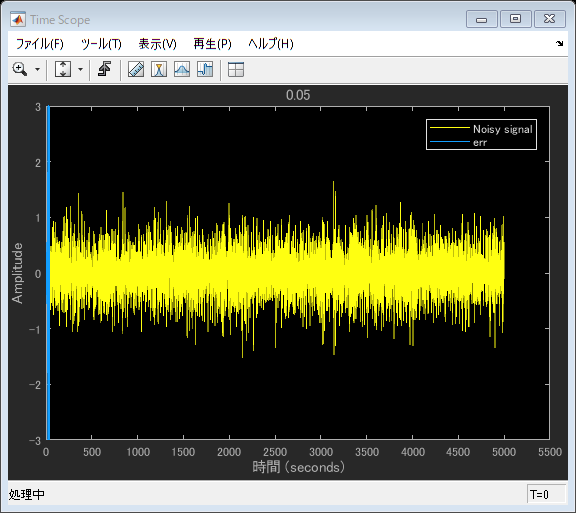

[~,e] = lmsfilt2(dp,xp);
TS2([xp,e]);

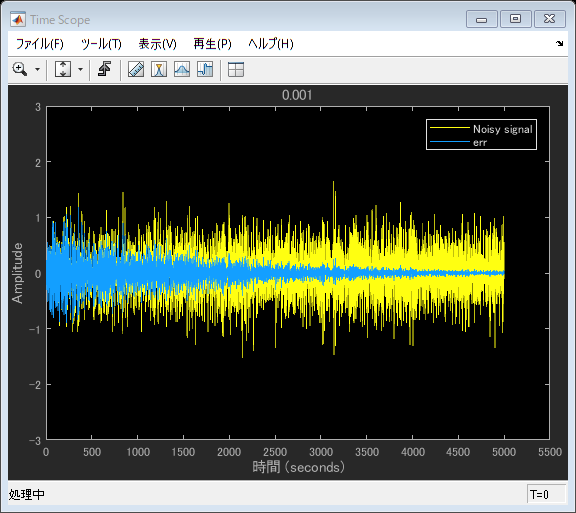

[~,e] = lmsfilt3(dp,xp);
TS3([xp,e]);

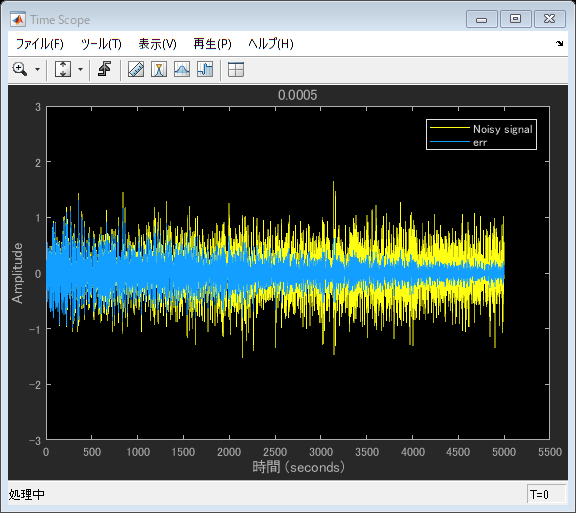

[~,e] = lmsfilt4(dp,xp);
TS4([xp,e]);